# Finding Values for the PI Controllers based on Input Poles

syms s a b l g Kp Ki Jp Ji Ci %define symbolic variables

Hvtheta = -s/l/(s^2 -g/l); % TF from velocity to angle of pendulum
K = Kp + Ki/s; % TF of the angle controller
J = Jp + Ji/s + Ci/s^2; % TF of the controller around the motor
M = a*b/(s+a); % TF of motor
Md = M/(1 + M*J); % TF of motor + feedbac controller around it

pretty(collect(Md));

                       2
                (a b) s
----------------------------------------
 3                 2
s  + (a + Jp a b) s  + Ji a b s + Ci a b



Htot = 1/(1 - Hvtheta*Md*K); % the total system function
pretty(simplify(Htot)) % display total system function

                                1
- ------------------------------------------------------------
                          2
                     a b s  (Ki + Kp s)
  -------------------------------------------------------- - 1
        2          2    3                    2
  (- l s  + g) (a s  + s  + Ci a b + Jp a b s  + Ji a b s)




% system parameters
g = 9.81;
l = 0.3879;
a = 17.84;
b =  0.009341;

Htot_subbed = subs(Htot) %substitue parameters found above

$$Htot\_subbed = \frac{1}{\frac{30019813371509505425\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{69877851818280615936\,\left(s^{2}-\frac{10900}{431}\right)\,\left(\frac{1200792534860380217\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{7205759403792793600\,\left(s+\frac{446}{25}\right)}+1\right)\,\left(s+\frac{446}{25}\right)}+1}$$

i = sqrt(-1);
% Choosing Poles
p1 = -1.5;
p2 = -2 ;
p3 = -2.5;
p4 = -2 

p4 = -2

p5 = -.5 ;

%target polynomial
target_polynomial = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)

$$target\_polynomial = {\left(s+2\right)}^{2}\,\left(s+\frac{1}{2}\right)\,\left(s+\frac{3}{2}\right)\,\left(s+\frac{5}{2}\right)$$


%find denominator
[n d] = numden(Htot_subbed);
% find the coefficients of the denominator polynomia
coeffs_denom = coeffs(d,s);
% divide out the coefficient of the highest power term
coeffs_denom = coeffs(d,s)/(coeffs_denom(end));
% find coefficients of target polynomia
coeffs_tgt = coeffs(target_polynomial,s);
% solve the system of equations setting the coefficients of the 
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom == coeffs_tgt, Jp, Ji, Kp, Ki, Ci);

% display the solutions as double precision numbers
Jp = double(solutions.Jp)

Jp = -56.0478

Ji = double(solutions.Ji)

Ji = -7.2371

Kp = double(solutions.Kp)

Kp = 126.2698

Ki = double(solutions.Ki)

Ki = 600.8712

Ci = double(solutions.Ci)

Ci = -1.7796

TFH =
 
  3.509e80 s^8 + 9.243e81 s^7 + 4.391e82 s^6 - 2.414e83 s^5 - 1.337e84 s^4 + 1.936e83 s^3 + 4.695e82 s^2
  ------------------------------------------------------------------------------------------------------
  3.509e80 s^8 + 9.243e81 s^7 + 6.295e82 s^6 + 1.888e83 s^5 + 2.791e83 s^4 + 1.936e83 s^3 + 4.695e82 s^2
 
Continuous-time transfer function.



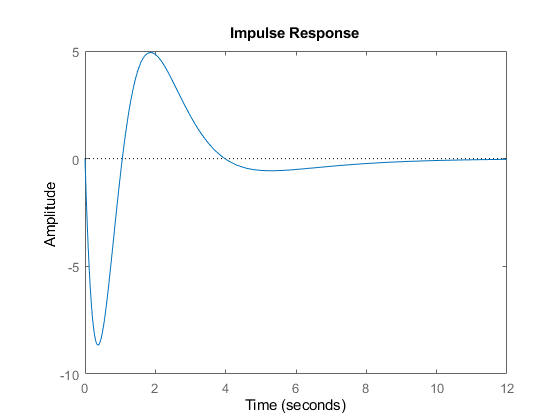


impulse_response_from_sym_expression(subs(Htot))

function h = impulse_response_from_sym_expression(H)

    TFstr = char(H);

    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression: "TF = (s+2)/(s^2+5*s+9)"
    eval(['TFH = ',TFstr]);
    impulse(TFH);

end